# Práctica 2

## Introducción

En esta práctica se explora la aplicación del método numérico de Runge-Kutta de orden 4 para la resolución de ecuaciones diferenciales ordinarias (EDO) y sistemas de EDO acopladas. Este método normalmente se utiliza en problemas de matemáticas aplicadas y física debido a que proporciona soluciones numéricas precisas y eficientes para las EDO de primer y segundo orden.

Primero, se abordará el caso de una EDO de primer orden y compararemos la solución numérica obtenida con el método de Runge-Kutta con su solución analítica. Luego, se utilizará el método para resolver sistemas de EDO acopladas y una EDO de segundo orden, en particular, una de un oscilador armónico simple. Finalmente, se aplicarádicho método para resolver dos modelos epidemiológicos:

- Modelo SIS

- Modelo SIR

Además, se analizará cómo varía el comportamiento de estos modelos en función de diferentes condiciones iniciales y parámetros. Estas simulaciones permitirán comprender la dinámica de las epidemias y cómo se propagan las enfermedades en una población haciendo uso de dichos modelos.

## Desarrollo

A continuación se comienza con el desarrollo de la práctica.

### Ejercicio 1

*Resolver la siguiente EDO de primer orden mediante el método de RungeKutta de orden 4. Resolver también la EDO analíticamente. Comparar las soluciones.*


$$
\frac{df(t)}{dt} \equiv f'(t) = -5f(t), \quad f(0) = 100
$$


#### *Solución Analítica*

A continuación se definen los pasos para obtener la solución analítica de la ecuación diferencial

**Paso 1:** Identificar tipo de ecuación diferencial


$$
\text{Ec. dif. lineal de primer orden:} \quad \frac{df(t)}{dt} + 5f(t) = 0
$$


**Paso 2:** Sacar el factor integrante


$$
\text{Factor integrante:} \quad e^{\int 5 dt} = e^{5t}
$$


**Paso 3:** Multiplicar la ecuación diferencial por el factor integrante


$$
e^{5t} \frac{df(t)}{dt} + 5e^{5t} f(t) = 0
$$


**Paso 4:** Se observa que el lado izquierdo es la derivada del producto del factor integrante y la función


$$
\frac{d}{dt} (e^{5t} f(t)) \equiv e^{5t} \frac{df(t)}{dt} + 5e^{5t} f(t) = 0
$$


**Paso 5:** Integrar ambos lados


$$
\int \frac{d}{dt} (e^{5t} f(t)) dt = \int 0 dt
$$


**Paso 6:** Resolver las integrales y despejar la función


$$
e^{5t} f(t) = C \quad \Rightarrow \quad f(t) = Ce^{-5t}
$$


**Paso 7:** Utilizar la condición inicial para obtener la constante C y definir solución analítica


$$
f(0) = Ce^{-5(0)} = C \quad \Rightarrow \quad C = 100
$$



$$
f(t) = 100e^{-5t}

$$


Una vez obtenemos la solución analítica calculamos 100 valores equitativamente distribuidos entre t = 0 y t = 2 para su posterior comparación con la solución numérica (*RungeKutta de cuarta orden*)

% Solución analítica
t0 = 0; % Tiempo inicial
tf = 2; % Tiempo final
N_steps = 100; % Número de pasos
t = linspace(t0, tf, N_steps + 1); % Array de tiempos
f_analytical = 100 * exp(-5 * t); % Solución analítica

#### *Solución Numérica*

A continuación se calculan los valores de la solución de la ecuación diferencial propuesta mediante el método de *RungeKutta de cuarto orden* para 100 valores equitativamente distribuidos entre t = 0 y t = 2. 

% Definición de la EDO y parámetros
f = @(t, r) -5 * r; % Definición de la función f(t)

t0 = 0; % Tiempo inicial
tf = 2; % Tiempo final
N_steps = 100; % Número de pasos
dt = (tf - t0) / N_steps; % Tamaño del paso
t = linspace(t0, tf, N_steps + 1); % Array de tiempos

r = zeros(size(t)); % Array vacío de valores de r(t)
r(1) = 100; % Condición inicial

% Método de Runge-Kutta de cuarto orden
for i = 2:N_steps+1
    k1 = f(t(i-1), r(i-1));
    k2 = f(t(i-1) + 0.5 * dt, r(i-1) + 0.5 * dt * k1);
    k3 = f(t(i-1) + 0.5 * dt, r(i-1) + 0.5 * dt * k2);
    k4 = f(t(i-1) + dt, r(i-1) + dt * k3);
    r(i) = r(i-1) + (dt / 6) * (k1 + 2 * k2 + 2 * k3 + k4);
end

#### Comparación

Finalmente, comparamos ambas soluciones:

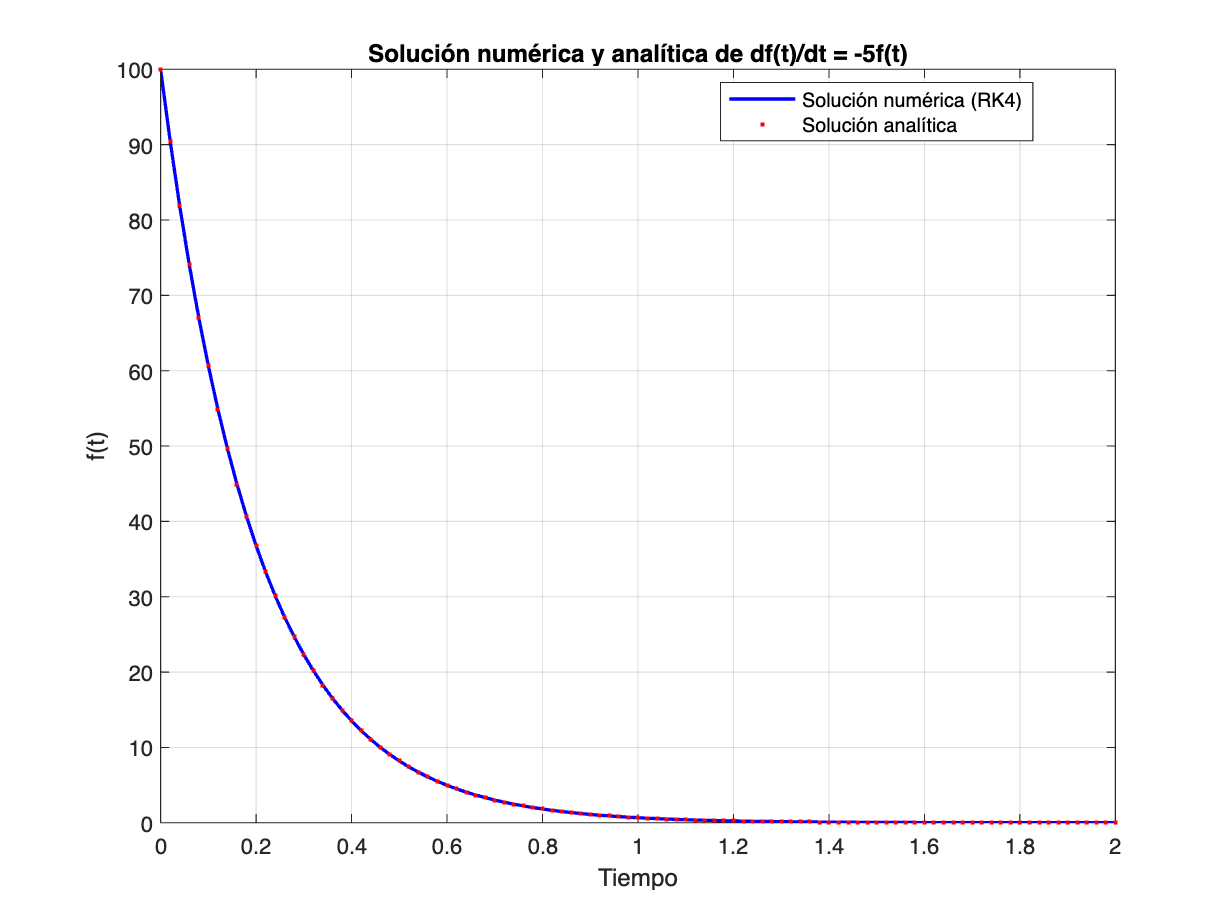

% Graficar solución numérica y analítica en un mismo plot
plot(t, r, 'b', t, f_analytical, '.r', 'LineWidth', 1.5);
xlabel('Tiempo');
ylabel('f(t)');
title('Solución numérica y analítica de df(t)/dt = -5f(t)');
legend('Solución numérica (RK4)', 'Solución analítica', 'Location', 'best');
grid on;

Podemos observar como obtenemos el mismo comportamiento tanto con la solución analítica como con la aproximación mediante el método *RungeKutta de cuarto orden*.

### Ejercicio 2

clc, clear

*Resolver el siguiente sistema de ecuaciones acopladas mediante el método de Runge-Kutta de orden 4.*


$$\begin{cases}
a'(t) = a(t) b^3(t) + b(t) \sin^2(a(t))\\
b'(t) = (| \cos(t)| + 1.1) b^2(t) a(t)\\
\end{cases} \text {, con } 
\begin{cases}
a(0) = 0.1, \\
b(0) = 0.2.
\end{cases}

$$


#### *Solución numérica*

A continuación se muestra la resolución del sistema de ecuaciones acopladas mediante el método *RungeKutta de cuarto orden*

% Definición de las funciones
f = @(t, a, b) a * b^3 + b * sin(a)^2;
g = @(t, a, b) (abs(cos(t)) + 1.1) * b^2 * a;

% Condiciones iniciales
a0 = 0.1;
b0 = 0.2;

% Parámetros del método numérico
t0 = 0;
tf = 14; % Por ejemplo, un tiempo final de 10
N_steps = 1000;
dt = (tf - t0) / N_steps;

% Arrays para almacenar las soluciones
t = linspace(t0, tf, N_steps + 1);
a = zeros(size(t));
b = zeros(size(t));
a(1) = a0;
b(1) = b0;

% Método de Runge-Kutta de cuarto orden
for i = 2:N_steps+1
    k1 = f(t(i-1), a(i-1), b(i-1));
    m1 = g(t(i-1), a(i-1), b(i-1));
    k2 = f(t(i-1) + 0.5 * dt, a(i-1) + 0.5 * dt * k1, b(i-1) + 0.5 * dt * m1);
    m2 = g(t(i-1) + 0.5 * dt, a(i-1) + 0.5 * dt * k1, b(i-1) + 0.5 * dt * m1);
    k3 = f(t(i-1) + 0.5 * dt, a(i-1) + 0.5 * dt * k2, b(i-1) + 0.5 * dt * m2);
    m3 = g(t(i-1) + 0.5 * dt, a(i-1) + 0.5 * dt * k2, b(i-1) + 0.5 * dt * m2);
    k4 = f(t(i-1) + dt, a(i-1) + dt * k3, b(i-1) + dt * m3);
    m4 = g(t(i-1) + dt, a(i-1) + dt * k3, b(i-1) + dt * m3);
    a(i) = a(i-1) + (dt / 6) * (k1 + 2 * k2 + 2 * k3 + k4);
    b(i) = b(i-1) + (dt / 6) * (m1 + 2 * m2 + 2 * m3 + m4);
end

#### *Visualización de resultados*

Posteriormente, se grafican y observan los resultados.

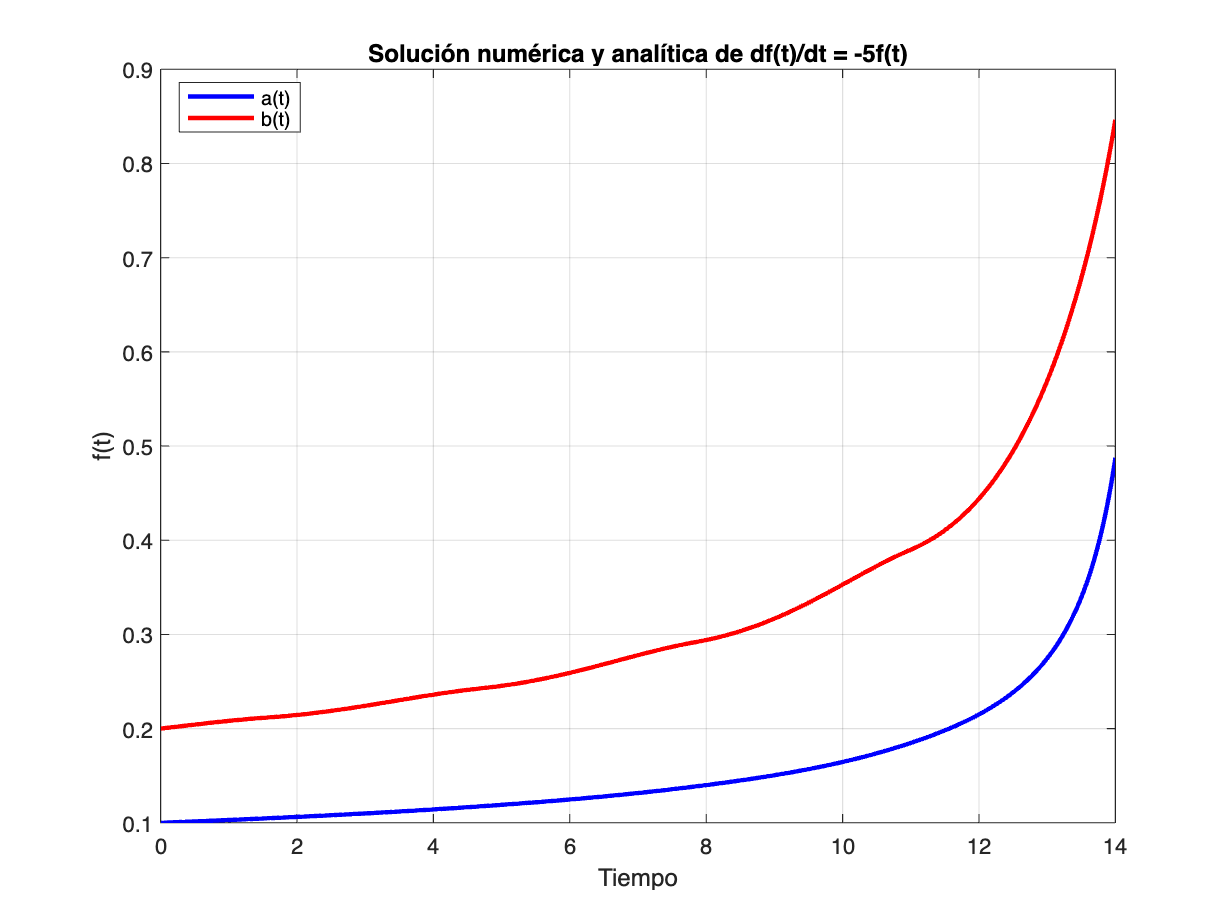

% Graficar solución numérica y analítica en un mismo plot
plot(t, a, 'b', t, b, 'r', 'LineWidth', 2);
xlabel('Tiempo');
ylabel('f(t)');
title('Solución numérica y analítica de df(t)/dt = -5f(t)');
legend('a(t)', 'b(t)', 'Location', 'best');
grid on;

### Ejercicio 3

clc, clear

*Resolver la siguiente ecuación diferencial de orden 2. Para ello, expresarla como un sistema de dos EDOs de primer orden acoplada (una para la posición y otra para la velocidad). Esta es la EDO que describe un oscilador armónico simple. Resolver analíticamente la ecuación. Hacer un plot comparando las dos soluciones (analítica y numérica).*


$$
r''(t) + 52r(t) = 0, \quad r(0) = \frac{\pi}{2}, \quad r'(0) \equiv v(0) = 0.


$$


#### *Solución Analítica*

A continuación se definen los pasos para obtener la solución analítica de la ecuación diferencial:

**Paso 1:** Identificar el tipo de ecuación diferencial

*Ec. dif. lineal de 2do orden con coefs constantes*


$$

r''(t) + 52r(t) = 0
$$


**Paso 2:** Sacar y resolver la ecuación característica


$$
\text{Ecuación característica:} \quad m^2 + 52 = 0
$$



$$
m^2 = -52 \quad \Rightarrow \quad m = \pm \sqrt{-52} = \pm 2\sqrt{13}i
$$


**Paso 4:** Escribir solución general


$$
r(t) = C_1 \cos(2\sqrt{13}t) + C_2 \sin(2\sqrt{13}t)
$$


**Paso 5:** Usar condiciones iniciales para obtener las constantes C1 y C2 y definir la solución analítica


$$
r(0) = C_1 \cos(0) + C_2 \sin(0) = C_1 = \frac{\pi}{2} \\
r'(t) = -2\sqrt{13} C_1 \sin(2\sqrt{13}t) + 2\sqrt{13} C_2 \cos(2\sqrt{13}t) \\
r'(0) = 0 = -2\sqrt{13} C_1 \sin(0) + 2\sqrt{13} C_2 \cos(0) = 2\sqrt{13} C_2 \\
C_2 = 0
$$


*SOLUCIÓN:*


$$
r(t) = \frac{\pi}{2} \cos(2\sqrt{13}t)

$$


Una vez obtenemos la solución analítica calculamos 200 valores equitativamente distribuidos entre t = 0 y t = 4 para su posterior comparación con la solución numérica (*RungeKutta de cuarta orden*)

% Parámetros del método numérico
t0 = 0;
tf = 4; % Por ejemplo, un tiempo final de 2
N_steps = 200;

% Arrays para almacenar las soluciones
t = linspace(t0, tf, N_steps + 1);

% Solución analítica
r_analytical = pi/2 * cos(5 * t);

#### *Solución Numérica*

A continuación se calculan los valores de la solución de la ecuación diferencial propuesta mediante el método de *RungeKutta de cuarto orden* para 200 valores equitativamente distribuidos entre t = 0 y t = 4. 

% Definir las funciones
f = @(t, r, v) v;
g = @(t, r, v) -25 * r;

% Condiciones iniciales
r0 = pi/2;
v0 = 0;

% Parámetros del método numérico
t0 = 0;
tf = 4; % Por ejemplo, un tiempo final de 2
N_steps = 200;
dt = (tf - t0) / N_steps;

% Arrays para almacenar las soluciones
t = linspace(t0, tf, N_steps + 1);
r = zeros(size(t));
v = zeros(size(t));
r(1) = r0;
v(1) = v0;

% Método de Runge-Kutta de cuarto orden
for i = 2:N_steps+1
    k1 = f(t(i-1), r(i-1), v(i-1));
    m1 = g(t(i-1), r(i-1), v(i-1));
    k2 = f(t(i-1) + 0.5 * dt, r(i-1) + 0.5 * dt * k1, v(i-1) + 0.5 * dt * m1);
    m2 = g(t(i-1) + 0.5 * dt, r(i-1) + 0.5 * dt * k1, v(i-1) + 0.5 * dt * m1);
    k3 = f(t(i-1) + 0.5 * dt, r(i-1) + 0.5 * dt * k2, v(i-1) + 0.5 * dt * m2);
    m3 = g(t(i-1) + 0.5 * dt, r(i-1) + 0.5 * dt * k2, v(i-1) + 0.5 * dt * m2);
    k4 = f(t(i-1) + dt, r(i-1) + dt * k3, v(i-1) + dt * m3);
    m4 = g(t(i-1) + dt, r(i-1) + dt * k3, v(i-1) + dt * m3);
    r(i) = r(i-1) + (dt / 6) * (k1 + 2 * k2 + 2 * k3 + k4);
    v(i) = v(i-1) + (dt / 6) * (m1 + 2 * m2 + 2 * m3 + m4);
end


#### *Comparación*

Finalmente, se comparan los resultados de la solución analítica con la solución numérica.

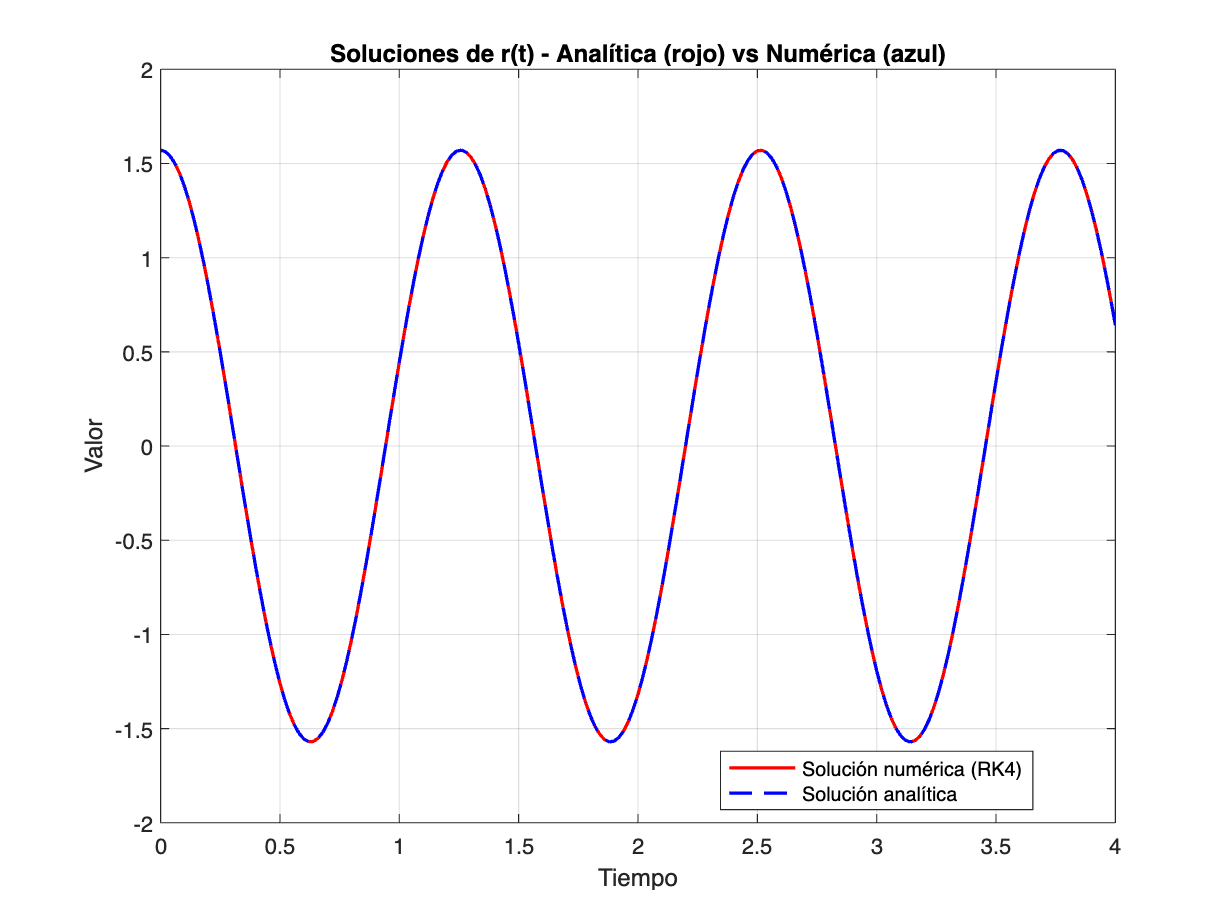

% Gráfica de las soluciones
figure;
plot(t, r, 'r', t, r_analytical, '--b', 'LineWidth', 1.5);
xlabel('Tiempo');
ylabel('Valor');
title('Soluciones de r(t) - Analítica (rojo) vs Numérica (azul)');
legend('Solución numérica (RK4)', 'Solución analítica', 'Location', 'best');
grid on;

Podemos observar como obtenemos el mismo comportamiento de oscilador armónico tanto con la solución analítica como con la aproximación mediante el método *RungeKutta de cuarto orden*.

### Ejercicio 4

clc, clear

*Modelo SIS. Utilizar el método Runge-Kutta de orden 4 para resolver el modelo SIS estudiado en clase para los parámetros α = 0.001, β = 0.22, con tmax = 60, y para los siguientes sets de condiciones iniciales:*


$$

\text{(a)} \quad S(0) = 1000, \quad I(0) = 10 \\
\text{(b)} \quad S(0) = 400, \quad I(0) = 10 \\
\text{(c)} \quad S(0) = 150, \quad I(0) = 140
$$


**Recordar que el modelo SIS (*****Susceptible-Infectious-Susceptible*****) es*****:***


$$

\frac{dS}{dt} = -\alpha SI + \beta I, \\
\frac{dI}{dt} = \alpha SI - \beta I,

$$


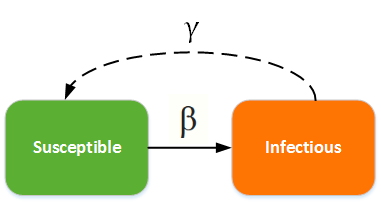

*(tener en cuenta que *α = β y β = γ*)*

#### *Solución Numérica y Visualización*

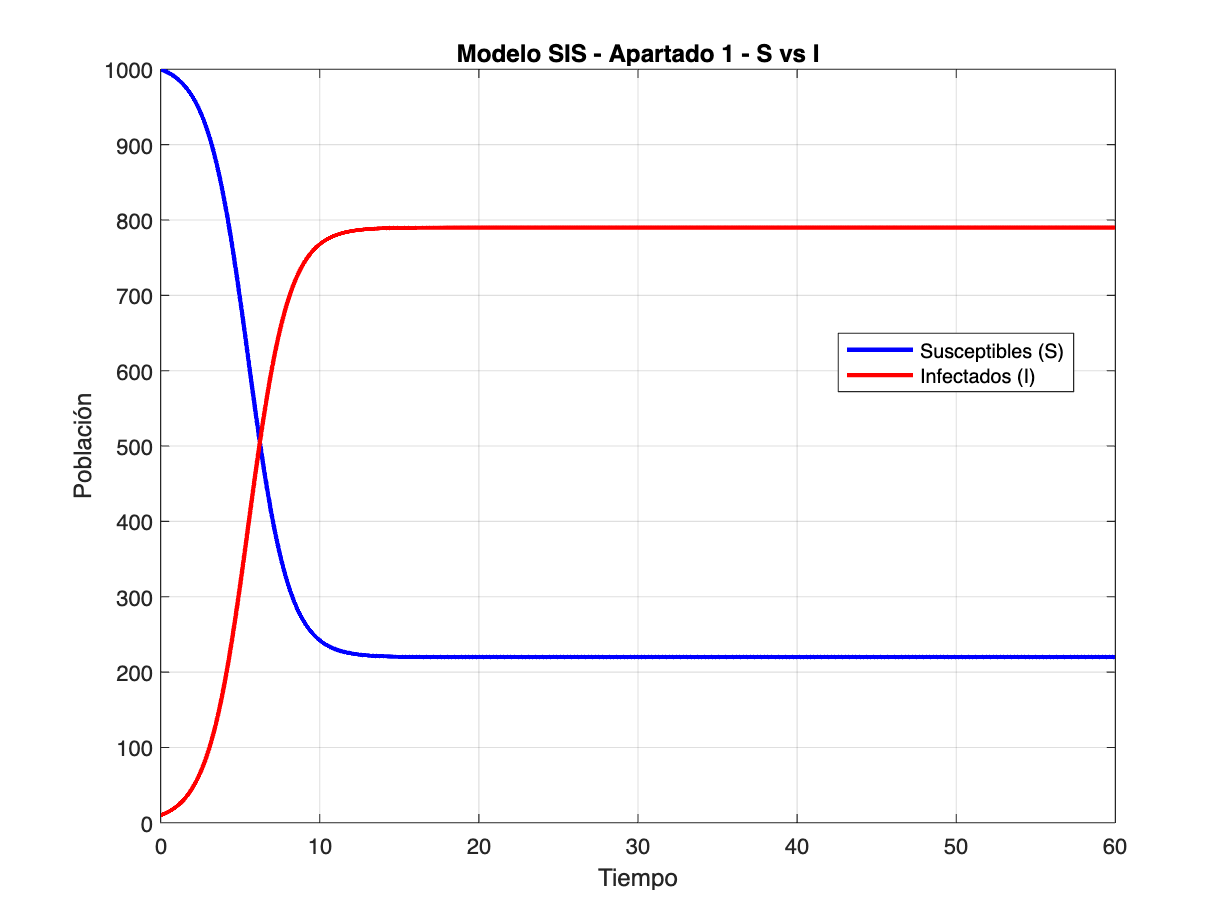

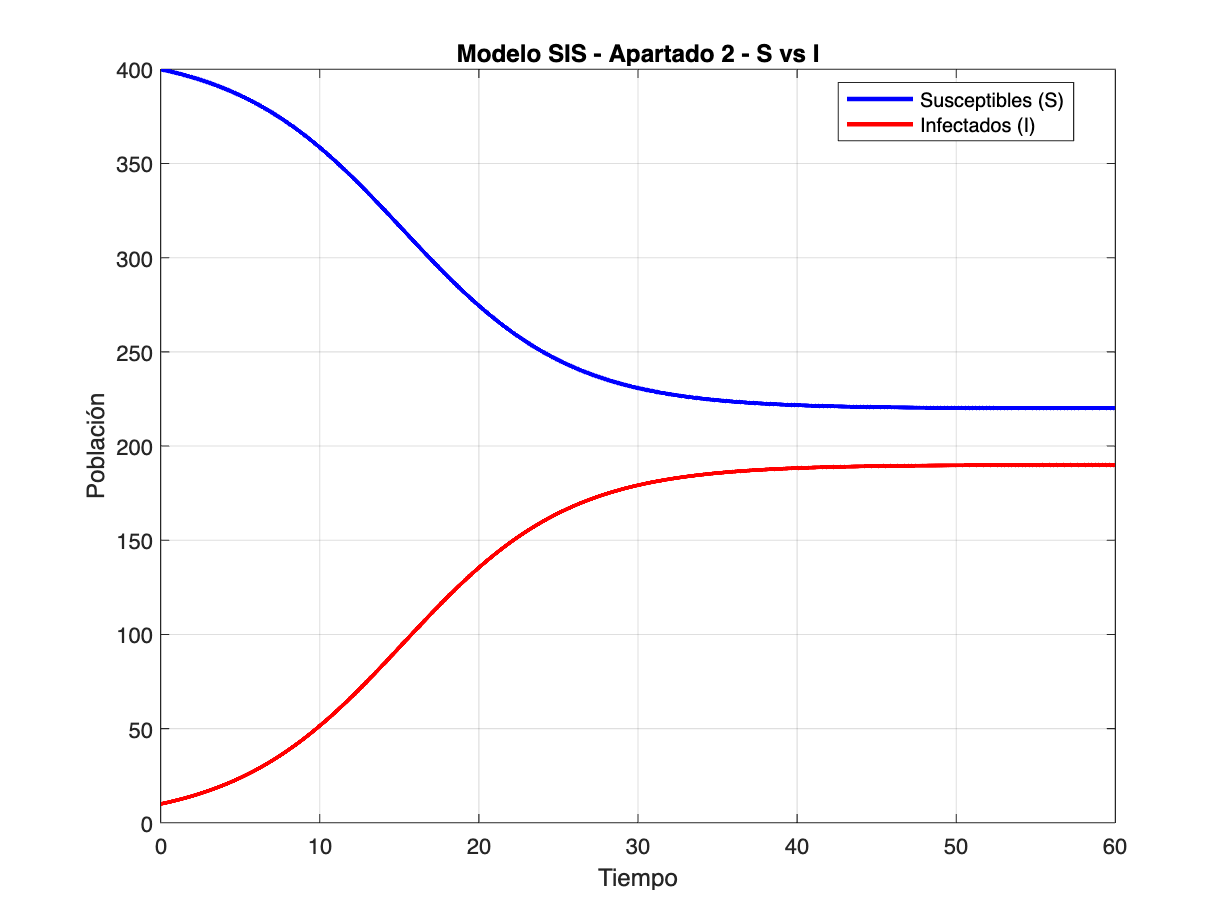

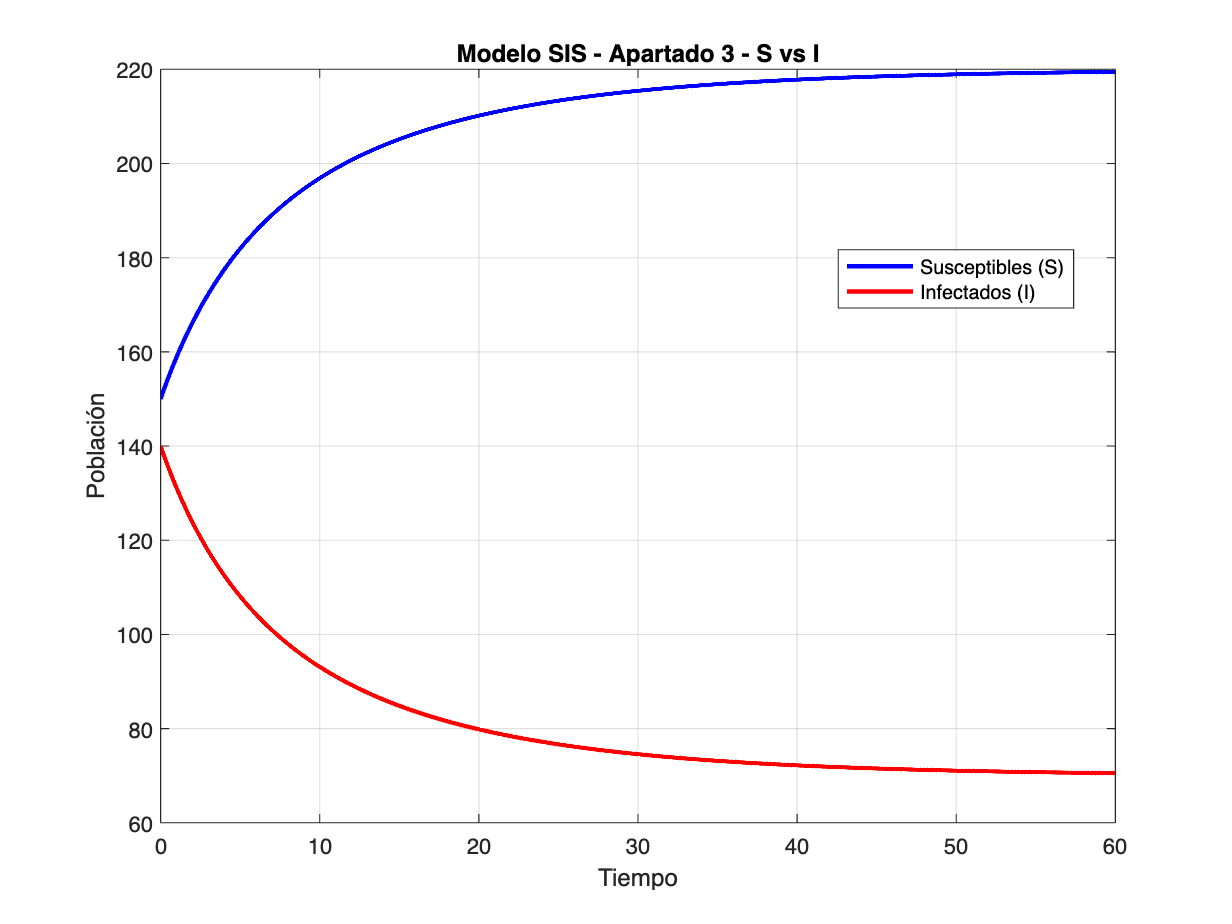

% Definición de las funciones
alpha = 0.001;
beta = 0.22;

f = @(S, I) -alpha * S * I + beta * I;
g = @(S, I) alpha * S * I - beta * I;

% Parámetros del método numérico
t0 = 0;
tmax = 60;
N_steps = 6000; % Dividir el intervalo de tiempo en pasos pequeños
dt = (tmax - t0) / N_steps;

% Sets de condiciones iniciales
sets_iniciales = [
    struct('S0', 1000, 'I0', 10);
    struct('S0', 400, 'I0', 10);
    struct('S0', 150, 'I0', 140)
];

for set = 1:length(sets_iniciales)
    S0 = sets_iniciales(set).S0;
    I0 = sets_iniciales(set).I0;
    
    % Arrays para almacenar las soluciones
    t = linspace(t0, tmax, N_steps + 1);
    S = zeros(size(t));
    I = zeros(size(t));
    S(1) = S0;
    I(1) = I0;

    % Método de Runge-Kutta de cuarto orden
    for i = 2:N_steps+1
        k1 = f(S(i-1), I(i-1));
        m1 = g(S(i-1), I(i-1));
        k2 = f(S(i-1) + 0.5 * dt * k1, I(i-1) + 0.5 * dt * m1);
        m2 = g(S(i-1) + 0.5 * dt * k1, I(i-1) + 0.5 * dt * m1);
        k3 = f(S(i-1) + 0.5 * dt * k2, I(i-1) + 0.5 * dt * m2);
        m3 = g(S(i-1) + 0.5 * dt * k2, I(i-1) + 0.5 * dt * m2);
        k4 = f(S(i-1) + dt * k3, I(i-1) + dt * m3);
        m4 = g(S(i-1) + dt * k3, I(i-1) + dt * m3);
        S(i) = S(i-1) + (dt / 6) * (k1 + 2 * k2 + 2 * k3 + k4);
        I(i) = I(i-1) + (dt / 6) * (m1 + 2 * m2 + 2 * m3 + m4);
    end

    % Gráfica de las soluciones
    figure;
    plot(t, S, 'b', t, I, 'r', 'LineWidth', 2);
    xlabel('Tiempo');
    ylabel('Población');
    title(sprintf('Modelo SIS - Apartado %d - S vs I', set));
    legend('Susceptibles (S)', 'Infectados (I)', 'Location', 'best');
    grid on;
end

#### Preguntas

*1.Comentar si los resultados obtenidos encajan con lo que esperaríamos. 2.¿En qué caso se produce una epidemia?  3.¿Podíamos haber predicho esto mediante algún resultado analítico visto en clase?*

En el modelo SIS, nos encontramos dos tipos de individuos: los susceptibles (S) y los infectados (I) los cuales pueden regresar a ser susceptibles nuevamente. Los parámetros α y β representan las tasas de infección y recuperación respectivamente (en este caso, α = 0.001 y β = 0.22). Con estos parámetros y las condiciones iniciales dadas [(a) S(0) = 1000, I(0) = 10: (b) S(0) = 400, I(0) = 10: (c) S(0) = 150, I(0) = 140] podemos responder a las preguntas: 

- Las epidemias se producen en las condiciones iniciales del apartado (a)  (S(0) = 1000, I(0) = 10) y (b) (S(0) = 400, I(0) = 10)

- Sabiendo las condiciones iniciales y los parámetros tenemos dos casos con los que podemos diferenciar si se produce epidemia o no. Estos son:


$$
I(0) < N - \frac{\beta}{\alpha}\text{, se produce endemia y epidemia}\\
I(0) > N - \frac{\beta}{\alpha}\text{, se produce endemia pero no epidemia}

$$


            Con estas condiciones podemos comprobar para los apartados.


$$

\text{ (a) }I(0) = 10 \text{ y } S(0) = 1000 \text{ luego } N = 1010 \text{ entonces } 10 < 1010 - \frac{\beta}{\alpha} = 1010 - 220 = 790 \\\text{Se producirá epidemia}\\
\text{ (b) }I(0) = 10 \text{ y } S(0) = 400 \text{ luego } N = 410 \text{ entonces } 10 < 410 - \frac{\beta}{\alpha} = 410 - 220 = 190 \\\text{Se producirá epidemia}\\
\text{ (c) }I(0) = 140 \text{ y } S(0) = 150 \text{ luego } N = 290 \text{ entonces } 140 > 290 - \frac{\beta}{\alpha} = 290 - 220 = 70 \\\text{No se producirá epidemia}\\$$


            Podemos observar que los resultados obtenidos analíticamente se corresponden con los resultados obtenidos en MatLab.

### Ejercicio 5

clc, clear

*Modelo SIR. Utilizar el método Runge-Kutta de orden 4 para resolver el modelo SIR estudiado en clase para los parémetros α = 0.001, β = 0.22, con tmax = 60, y para los siguientes sets de condiciones iniciales:*


$$

\text{(a)} \quad S(0) = 1000, \quad I(0) = 10, \quad R(0) = 0, \\
\text{(b)} \quad S(0) = 400, \quad I(0) = 10, \quad R(0) = 0, \\
\text{(c)} \quad S(0) = 200, \quad I(0) = 10, \quad R(0) = 0.

$$


**Recordar que el modelo SIR (*****Susceptible-Infectious-Recovered*****) es*****:***


$$

\frac{dS}{dt} = -\alpha SI \\
\frac{dI}{dt} = \alpha SI - \beta I \\
\frac{dR}{dt} = \beta I

$$


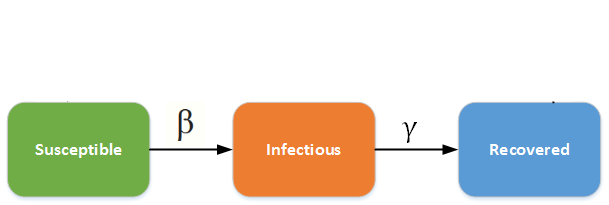

*(tener en cuenta que *α = β y β = γ*)*

#### *Solución Numérica y Visualización*

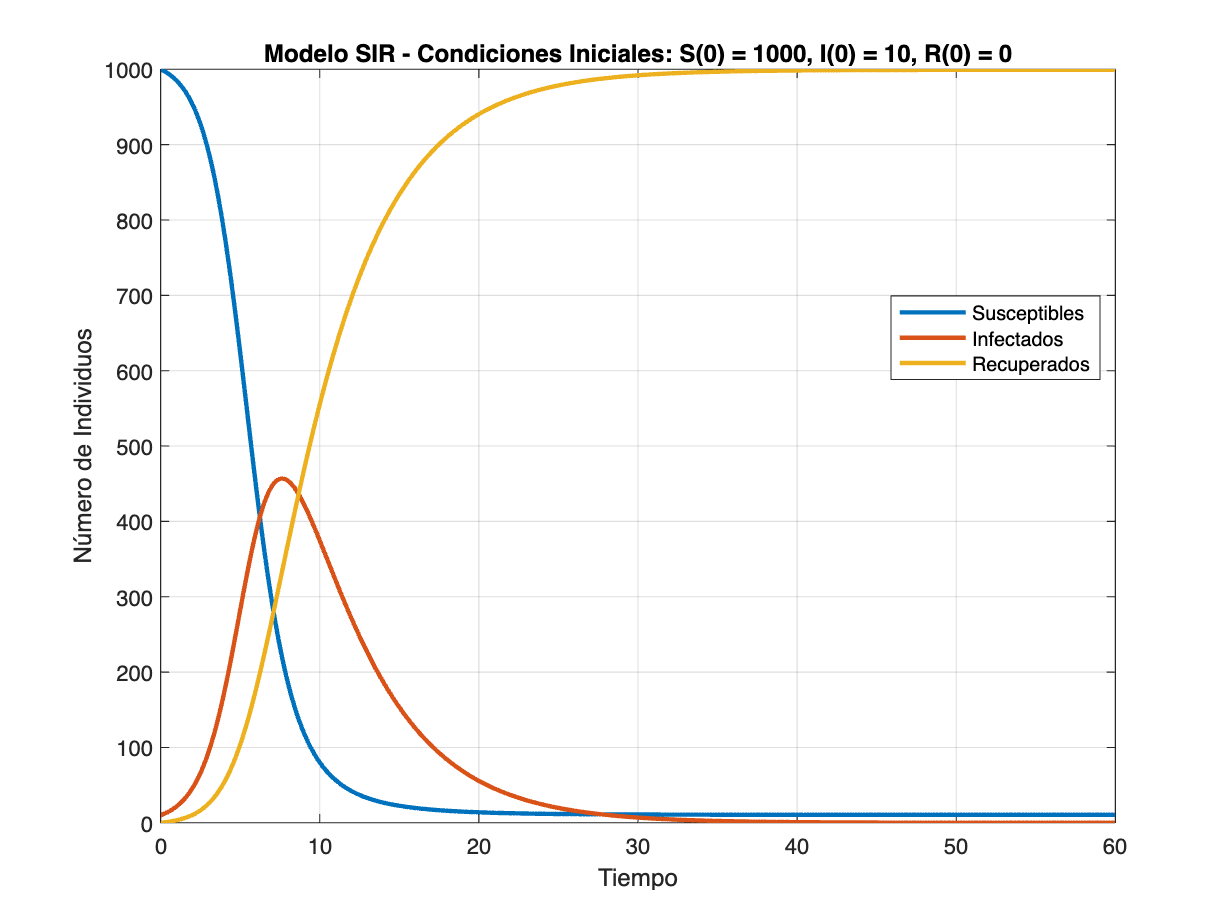

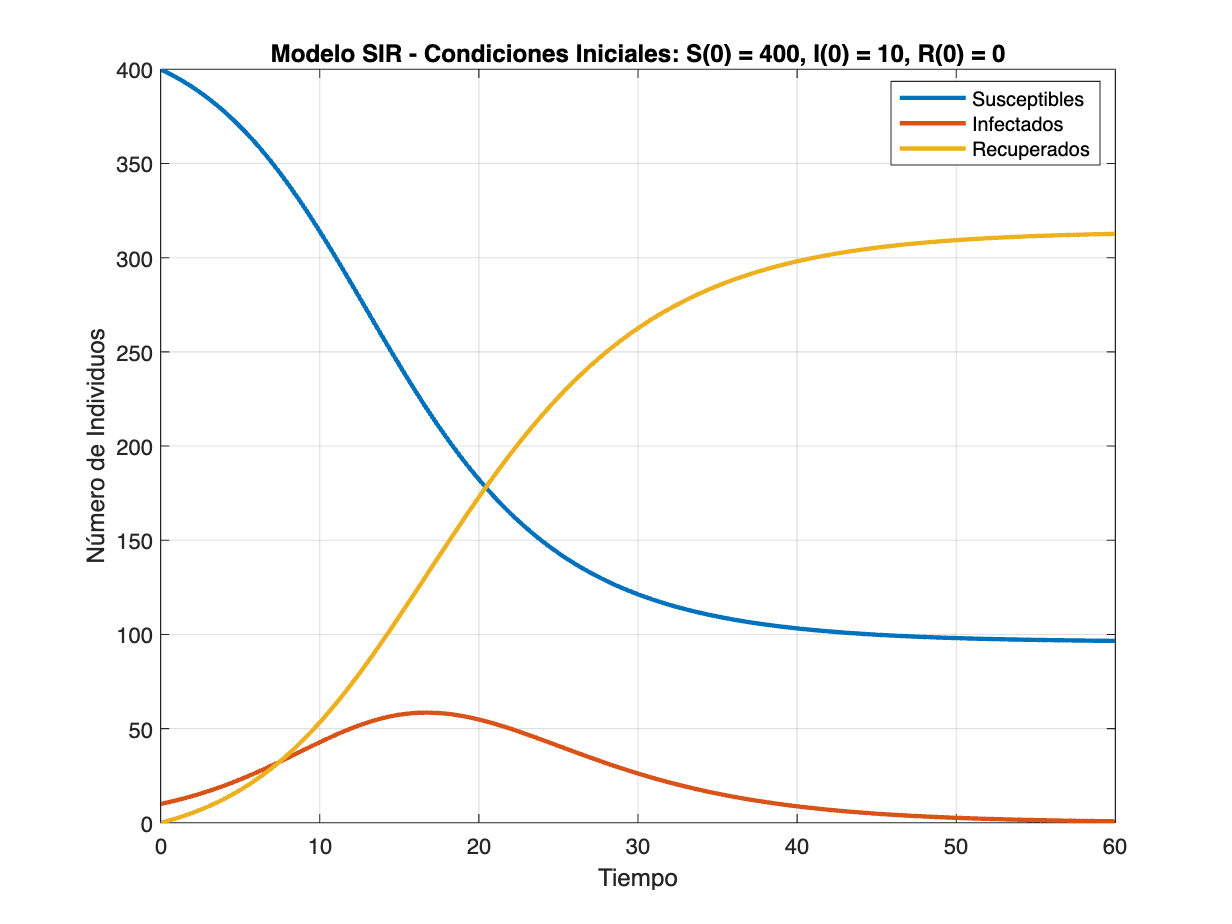

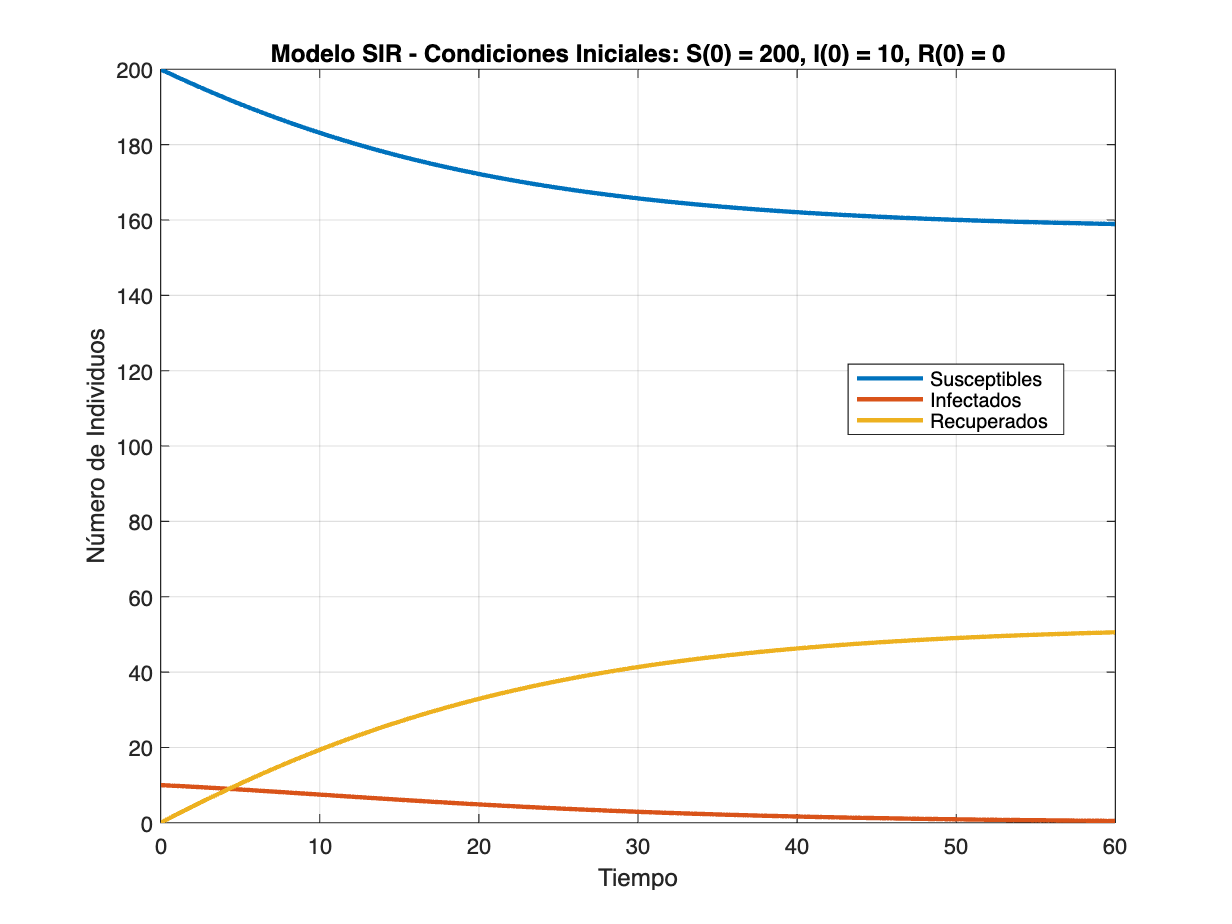

% Parámetros del modelo SIR
alpha = 0.001;
beta = 0.22;

% Condiciones iniciales para los tres casos
S0_values = [1000, 400, 200];
I0_values = [10, 10, 10];
R0_values = [0, 0, 0];

% Tiempo máximo y número de pasos
tmax = 60;
N_steps = 600;

% Funciones del modelo SIR
f_SIR = @(t, S, I, R) -alpha * S * I;
g_SIR = @(t, S, I, R) alpha * S * I - beta * I;
h_SIR = @(t, S, I, R) beta * I;

% Loop para cada conjunto de condiciones iniciales
for case_num = 1:length(S0_values)
    % Inicialización de variables
    SIR_t = linspace(0, tmax, N_steps+1);
    S = zeros(size(SIR_t));
    I = zeros(size(SIR_t));
    R = zeros(size(SIR_t));
    S(1) = S0_values(case_num);
    I(1) = I0_values(case_num);
    R(1) = R0_values(case_num);

    % Método de Runge-Kutta de orden 4
    for i = 2:N_steps+1
        k1 = f_SIR(SIR_t(i-1), S(i-1), I(i-1), R(i-1));
        m1 = g_SIR(SIR_t(i-1), S(i-1), I(i-1), R(i-1));
        n1 = h_SIR(SIR_t(i-1), S(i-1), I(i-1), R(i-1));

        k2 = f_SIR(SIR_t(i-1) + 0.5*(tmax/N_steps), S(i-1) + 0.5*(tmax/N_steps)*k1, I(i-1) + 0.5*(tmax/N_steps)*m1, R(i-1) + 0.5*(tmax/N_steps)*n1);
        m2 = g_SIR(SIR_t(i-1) + 0.5*(tmax/N_steps), S(i-1) + 0.5*(tmax/N_steps)*k1, I(i-1) + 0.5*(tmax/N_steps)*m1, R(i-1) + 0.5*(tmax/N_steps)*n1);
        n2 = h_SIR(SIR_t(i-1) + 0.5*(tmax/N_steps), S(i-1) + 0.5*(tmax/N_steps)*k1, I(i-1) + 0.5*(tmax/N_steps)*m1, R(i-1) + 0.5*(tmax/N_steps)*n1);

        k3 = f_SIR(SIR_t(i-1) + 0.5*(tmax/N_steps), S(i-1) + 0.5*(tmax/N_steps)*k2, I(i-1) + 0.5*(tmax/N_steps)*m2, R(i-1) + 0.5*(tmax/N_steps)*n2);
        m3 = g_SIR(SIR_t(i-1) + 0.5*(tmax/N_steps), S(i-1) + 0.5*(tmax/N_steps)*k2, I(i-1) + 0.5*(tmax/N_steps)*m2, R(i-1) + 0.5*(tmax/N_steps)*n2);
        n3 = h_SIR(SIR_t(i-1) + 0.5*(tmax/N_steps), S(i-1) + 0.5*(tmax/N_steps)*k2, I(i-1) + 0.5*(tmax/N_steps)*m2, R(i-1) + 0.5*(tmax/N_steps)*n2);

        k4 = f_SIR(SIR_t(i-1) + (tmax/N_steps), S(i-1) + (tmax/N_steps)*k3, I(i-1) + (tmax/N_steps)*m3, R(i-1) + (tmax/N_steps)*n3);
        m4 = g_SIR(SIR_t(i-1) + (tmax/N_steps), S(i-1) + (tmax/N_steps)*k3, I(i-1) + (tmax/N_steps)*m3, R(i-1) + (tmax/N_steps)*n3);
        n4 = h_SIR(SIR_t(i-1) + (tmax/N_steps), S(i-1) + (tmax/N_steps)*k3, I(i-1) + (tmax/N_steps)*m3, R(i-1) + (tmax/N_steps)*n3);

        S(i) = S(i-1) + (tmax/N_steps)*(k1 + 2*k2 + 2*k3 + k4)/6;
        I(i) = I(i-1) + (tmax/N_steps)*(m1 + 2*m2 + 2*m3 + m4)/6;
        R(i) = R(i-1) + (tmax/N_steps)*(n1 + 2*n2 + 2*n3 + n4)/6;
    end
    
    % Gráfico de las soluciones
    figure;
    plot(SIR_t, S, 'LineWidth', 2, 'DisplayName', 'Susceptibles');
    hold on;
    plot(SIR_t, I, 'LineWidth', 2, 'DisplayName', 'Infectados');
    plot(SIR_t, R, 'LineWidth', 2, 'DisplayName', 'Recuperados');
    xlabel('Tiempo');
    ylabel('Número de Individuos');
    title(['Modelo SIR - Condiciones Iniciales: S(0) = ', num2str(S0_values(case_num)), ', I(0) = ', num2str(I0_values(case_num)), ', R(0) = ', num2str(R0_values(case_num))]);
    legend('show', 'Location', 'Best');
    grid on;
end

#### Preguntas

*Comentar si los resultados obtenidos encajan con lo que esperaríıamos. ¿En qué caso se produce una epidemia? ¿Podíamos haber predicho esto mediante algún resultado analítico visto en clase?*

En el modelo SIR, las personas pasan de ser susceptibles (S) a infectadas (I) y luego se recuperan (R) siendo inmunes a una nueva infección. Los parámetros α y β representan las tasas de infección y recuperación, respectivamente (en este caso, α = 0.001 y β = 0.22). Con estos parámetros y las condiciones iniciales dadas [(a) S(0) = 1000, I(0) = 10, R(0) = 0 (b) S(0) = 400, I(0) = 10, R(0) = 0 (c) S(0) = 200, I(0) = 10, R(0) = 0] podemos responder a las preguntas: 

- Las epidemias se producen en las condiciones iniciales del apartado (a)  (S(0) = 1000, I(0) = 10, R(0) = 0) y (b) (S(0) = 400, I(0) = 10, R(0) = 0)

- Sabiendo las condiciones iniciales y los parámetros tenemos dos casos con los que podemos diferenciar si se produce epidemia o no. Estos son:


$$
S(0) > \frac{\beta}{\alpha}\text{, se produce epidemia}\\
S0) < \frac{\beta}{\alpha}\text{, no se produce epidemia}


$$


            Con estas condiciones podemos comprobar para los apartados.


$$\text{ (a) }S(0) = 1000 \text{ entonces } 1000 > \frac{\beta}{\alpha} = 220\\\text{Se producirá epidemia}\\
\text{ (a) }S(0) = 400 \text{ entonces } 400 > 220\\\text{Se producirá epidemia}\\
\text{ (a) }S(0) = 150 \text{ entonces } 150 < 220\\\text{No se producirá epidemia}\\
$$


            Podemos observar que los resultados obtenidos analíticamente se corresponden con los resultados obtenidos en MatLab.